%tests if the depth adjusting do anything good??
totalpix_raw = [];
totalpix_adj = [];
for i = 1:numel(raw_pixel.pixel_color)
    raw_frame = [raw_pixel.pixel_color{i}];
    if (~isempty(raw_frame))
        totalpix_raw = [totalpix_raw; raw_frame];
    end

    adj_frame = [adjflo{i}];
    if(~isempty(adj_frame))
        totalpix_adj = [totalpix_adj; adj_frame];
    end
end

%filter out only top 20 percentile of adj value?
%and exclude top 1
p11_20 = prctile(totalpix_adj(:, 1), 80);
p31_20 = prctile(totalpix_adj(:, 3), 80);
p11_1 = prctile(totalpix_adj(:, 1), 99);
p31_1 = prctile(totalpix_adj(:, 3), 99);

% Filter totalpix_adj to keep only values between the 1st and 20th percentiles
filter1 = (totalpix_adj(:, 1)>p11_20) & (totalpix_adj(:, 1)<p11_1);
filter2 = (totalpix_adj(:, 3)>p31_20) & (totalpix_adj(:, 1)<p31_1);
finalfilt = filter1 & filter2;
filtered_adj = totalpix_adj(finalfilt, :);

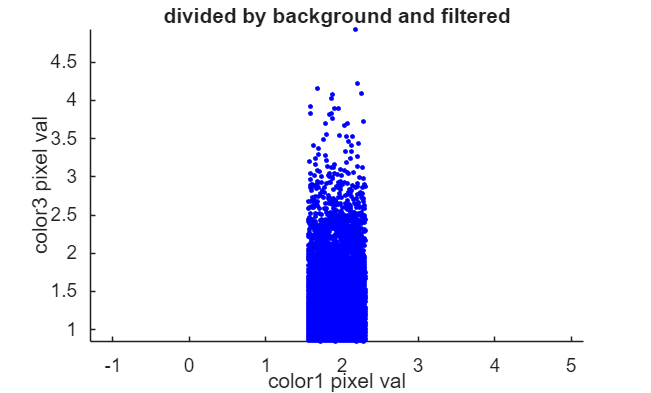

figure;
hold on;
scatter(filtered_adj(:, 1), filtered_adj(:, 3), 6, 'blue', 'filled');
xlabel('color1 pixel val');
ylabel('color3 pixel val');
title('divided by background and filtered');
axis equal;
hold off;

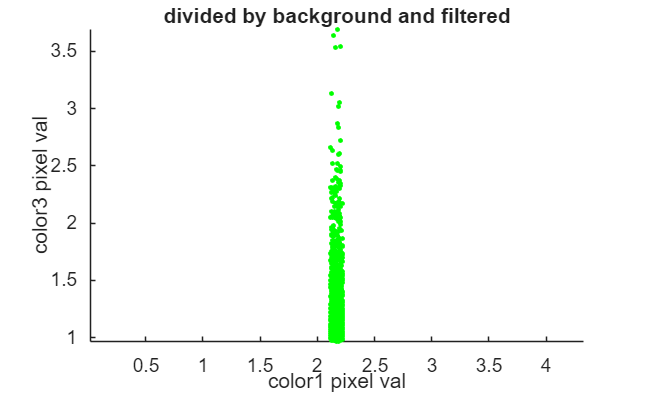

figure;
hold on;
scatter(filtered_adj(:, 1), filtered_adj(:, 3), 6, 'green', 'filled');
xlabel('color1 pixel val');
ylabel('color3 pixel val');
title('divided by background and filtered');
axis equal;
hold off;

coe_filt= zeros([2, 1]);
coe_filt(1, 1) = std(filtered_adj(:, 1))/mean(filtered_adj(:, 1));
coe_filt(2, 1) = std(filtered_adj(:, 3))/mean(filtered_adj(:, 3));

coe_raw = std(double(totalpix_raw(:, 1)))/mean(totalpix_raw(:, 1), 1);
coe_adj = std(double(totalpix_adj(:, 1)))/mean(totalpix_adj(:, 1), 1);


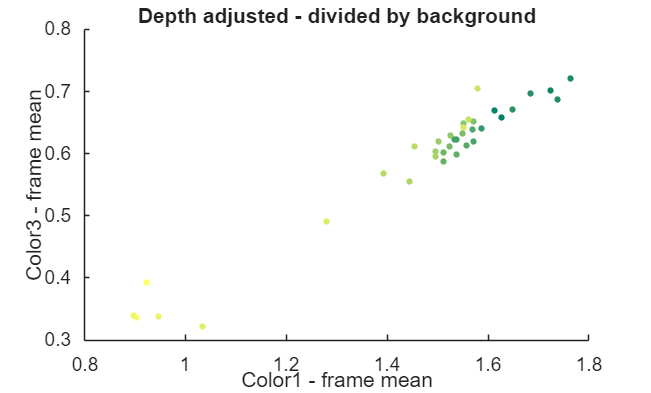

figure;
hold on;
camp = summer(36);
for j = 1:36
    adj_frame = [adjflo{j}];
    camp(j, :, :, :);
    scatter(mean(adj_frame(:, 1), 'all'), ...
        mean(adj_frame(:, 3),"all"), 10, camp(j, :, :, :),'filled');
end
title('Depth adjusted - divided by background');
xlabel('Color1 - frame mean');
ylabel('Color3 - frame mean');
hold off;

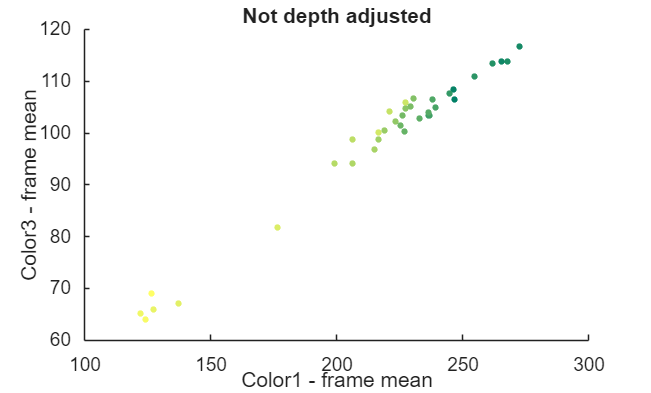

figure;
hold on;
camp = summer(36);
for j = 1:36
    adj_frame = [raw_pixel.pixel_color{j}];
    camp(j, :, :, :);
    scatter(mean(adj_frame(:, 1), 'all'), ...
        mean(adj_frame(:, 3),"all"),10, camp(j, :, :, :),'filled');
end
title('Not depth adjusted');
xlabel('Color1 - frame mean');
ylabel('Color3 - frame mean');
hold off;